# 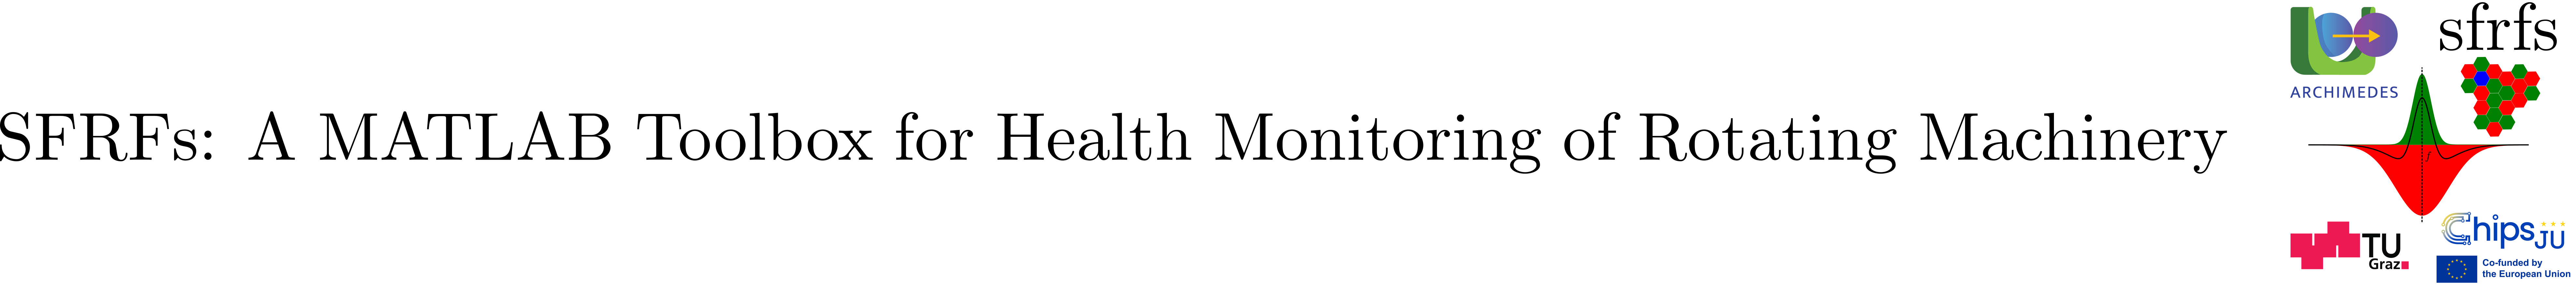

# FrequencyBankMasksSchema

## Summary

`FrequencyBankMasksSchema` centralizes the field-name constants used for accessing frequency-bank masks stored in the gain-functions table record produced by [`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx')).

## Description

This schema defines how center, surround, and opponent (contrast) frequency-bank gain masks are represented at the record level.

It ensures that downstream components can reliably access perceptual masks without relying on hard-coded strings or table-specific conventions.

The schema is tied to the perceptual layer of the toolbox, where gain masks implement frequency selectivity prior to response aggregation and contrast mapping.

### Defined fields

### Notes

- `CENTER` and `SURROUND` correspond to the primary gain masks produced by the masking stage.

- `CONTRAST` is a derived artifact representing center–surround opponency, stored explicitly for downstream consumers (e.g., response computation, visualization).

- These fields describe *record-level mask structs stored inside table cells*; they are distinct from the standalone struct schemas in `+structs`.

### See also

[`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [`tables.GainFunctionsTableSchema`](matlab:open('./GainFunctionsTableSchema.mlx')), [`ReceptiveFieldResponseFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx'))

## Example

% Minimal illustrative example (synthetic masks)

% import definitions
import structs.FrequencyBankMasksSchema

nBins = 8;

% Build frequency-bank masks
center   = ones(nBins,1);
surround = 0.5 * ones(nBins,1);
contrast = center - surround;

% Store using schema keys
masks = struct();
masks.(FrequencyBankMasksSchema.CENTER)   = center;
masks.(FrequencyBankMasksSchema.SURROUND) = surround;
masks.(FrequencyBankMasksSchema.CONTRAST) = contrast;

% Access via schema
C = masks.(FrequencyBankMasksSchema.CENTER);
S = masks.(FrequencyBankMasksSchema.SURROUND);
D = masks.(FrequencyBankMasksSchema.CONTRAST);

disp("Fields: " + strjoin(string(fieldnames(masks)), ", "));

Fields: CenterFrequencyBankMask, SurroundFrequencyBankMask, ContrastFrequencyBankMask


disp("Contrast: " + mat2str(D.'));

Contrast: [0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5]


## API documentation

### MATLAB help

help structs.FrequencyBankMasksSchema

  FrequencyBankMasksSchema  Field name constants for frequency-bank masks
 
  Defines the struct fields stored in the FrequencyBankMasks table column
  produced by ReceptiveFieldGainFunctions.
 
  This schema describes fault-condition record-level frequency masks
  computed by RFGFs.
 
  Notes:
    - CENTER and SURROUND are primary masks produced by the masking stage.
    - CONTRAST is the opponent (center–surround) channel stored as a stable,
      derived artifact for downstream consumers.
 
  See also: ReceptiveFieldGainFunctions, tables.GainFunctionsTableSchema

    Documentation for structs.FrequencyBankMasksSchema



## Source code

The source of the class can be found in [`FrequencyBankMasksSchema`](matlab:open('../../+structs/FrequencyBankMasksSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).